% ejercicio3_circular_3D.m
% Trayectoria circular con animación 3D en lugar de 2D

clear; close all; clc;

%% Parámetros y tiempo
r    = 0.1;     % radio de rueda [m]
L    = 0.4;     % separación ejes [m]
R    = 15;      % radio de la circunferencia [m]
v    = 1.0;     % velocidad lineal deseada [m/s]
omega_c = v/R;  % velocidad angular del cuerpo [rad/s]
dt   = 1;       % paso de muestreo [s]
t    = 0:dt:2*pi*R/v;  % tiempo para una vuelta completa
N    = length(t);

%% Cálculo de ω_R y ω_L constantes
omega_R = (v/r) + (L*omega_c)/(2*r);
omega_L = (v/r) - (L*omega_c)/(2*r);
wR = omega_R * ones(N,1);
wL = omega_L * ones(N,1);

%% Cinemática directa
v_vec = v * ones(N,1);
w_vec = omega_c * ones(N,1);

%% Integración Euler (arranca en (R,0) mirando +Y)
x = zeros(N,1); 
y = zeros(N,1);
phi = zeros(N,1);
x(1)   = R;
y(1)   = 0;
phi(1) = pi/2;
for k = 1:N-1
    phi(k+1) = phi(k) + w_vec(k)*dt;
    x(k+1)   = x(k)   + v_vec(k)*cos(phi(k))*dt;
    y(k+1)   = y(k)   + v_vec(k)*sin(phi(k))*dt;
end

%% Tabla de resultados
T3 = table( ...
  t', wR, wL, x, y, rad2deg(phi), ...
  'VariableNames', ...
  {'t_s','omega_R','omega_L','x_m','y_m','theta_deg'});
disp(T3);

    t_s    omega_R    omega_L      x_m         y_m       theta_deg
    ___    _______    _______    ________    ________    _________

     0     10.133     9.8667           15           0         90  
     1     10.133     9.8667           15           1      93.82  
     2     10.133     9.8667       14.933      1.9978     97.639  
     3     10.133     9.8667         14.8      2.9889     101.46  
     4     10.133     9.8667       14.602       3.969     105.28  
     5     10.133     9.8667       14.338      4.9336      109.1  
     6     10.133     9.8667       14.011      5.8786     112.92  
     7     10.133     9.8667       13.622      6.7996     116.74  
     8     10.133     9.8667       13.172      7.6927     120.56  
     9     10.133     9.8667       12.663      8.5538     

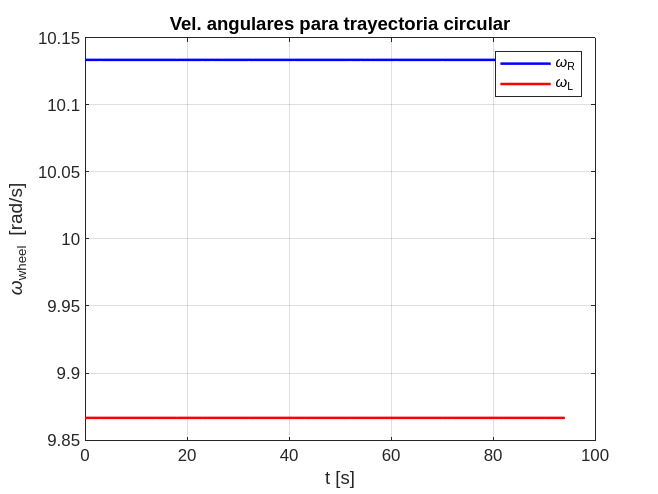


%% Gráfica ω_R y ω_L
figure;
plot(t, wR,'b-', t, wL,'r-','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\omega_{wheel} [rad/s]')
legend('\omega_R','\omega_L'), title('Vel. angulares para trayectoria circular')

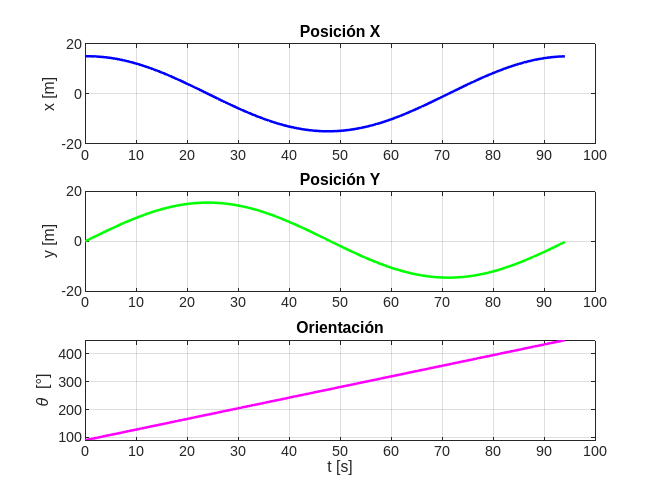


%% Gráficas de pose
figure;
subplot(3,1,1)
plot(t, x,'b-','LineWidth',1.5), grid on, ylabel('x [m]'), title('Posición X')
subplot(3,1,2)
plot(t, y,'g-','LineWidth',1.5), grid on, ylabel('y [m]'), title('Posición Y')
subplot(3,1,3)
plot(t, rad2deg(phi),'m-','LineWidth',1.5), grid on
xlabel('t [s]'), ylabel('\theta [°]'), title('Orientación')

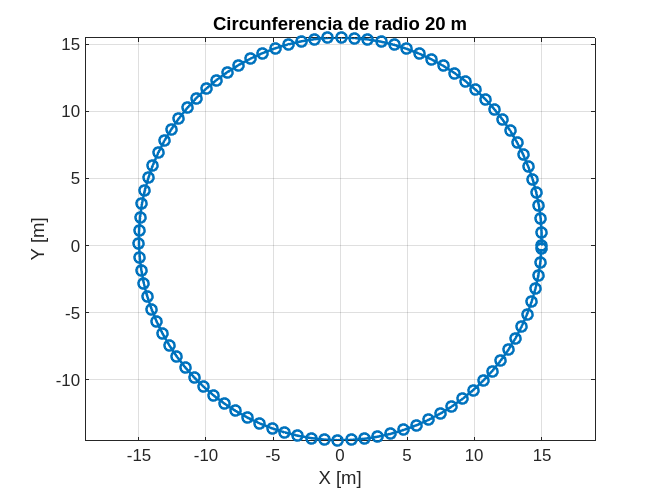


%% Trayectoria estática XY
figure;
plot(x, y,'-o','LineWidth',1.5), axis equal, grid on
xlabel('X [m]'), ylabel('Y [m]'), title('Circunferencia de radio 20 m')

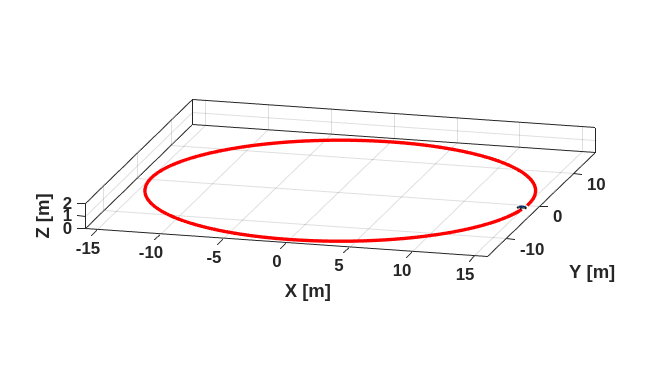


%% == SUSTITUIDA la animación 2D por animación 3D ==
% Simulación virtual 3D con MobileRobot_5 y MobilePlot_4

figure('Name','Animación 3D','NumberTitle','off');
set(gcf,'Color','white');
set(gca,'FontWeight','bold');
screen = get(0,'ScreenSize');
set(gcf,'Position',screen);
camlight('headlight');
axis equal; grid on; box on; hold on;
xlabel('X [m]'); ylabel('Y [m]'); zlabel('Z [m]');
view([15 15]);
axis([min(x)-1, max(x)+1, min(y)-1, max(y)+1, 0, 2]);

% Carga del modelo y escala
MobileRobot_5;
scale = 4;

% Dibuja estado inicial
H3D_robot = MobilePlot_4(x(1), y(1), phi(1), scale);
H3D_path  = plot3(x(1), y(1), 0, 'r-','LineWidth',2);

% Bucle de animación 3D
for k = 2:N
    delete(H3D_robot);
    set(H3D_path, 'XData', x(1:k), 'YData', y(1:k), 'ZData', zeros(1,k));
    H3D_robot = MobilePlot_4(x(k), y(k), phi(k), scale);
    pause(dt);
end